Problem-2)

HRV signal ----    ------   ------  R_R Interval of Each beat in an ECG signal!

clear; clc; close all;
%% A) Generate ECG Signal:
fs = 1024 ; % Sampling Frequency (Hz)
ts = 1/fs; % Time domain sampling

Signal_Length = 0.8; % 0.8 seconds

Number_of_samples = round(Signal_Length/ts) ;
ECG_Sig = ecg(Number_of_samples);

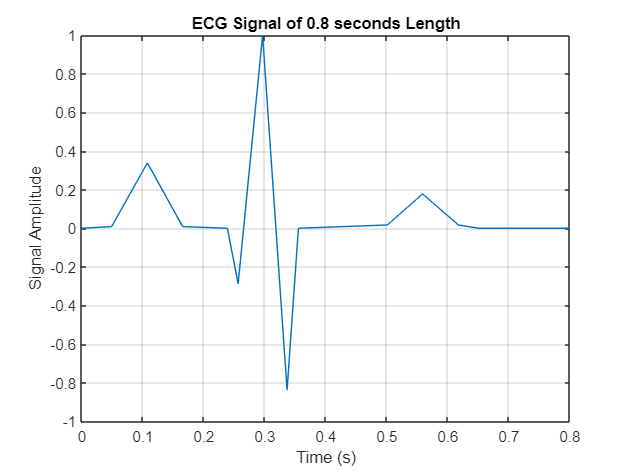

%% Plotting of ECG Signal
figure(1)
plot(linspace(0,Signal_Length,Number_of_samples) , ECG_Sig)
grid on
title("ECG Signal of 0.8 seconds Length");
xlabel("Time (s)")
ylabel("Signal Amplitude")

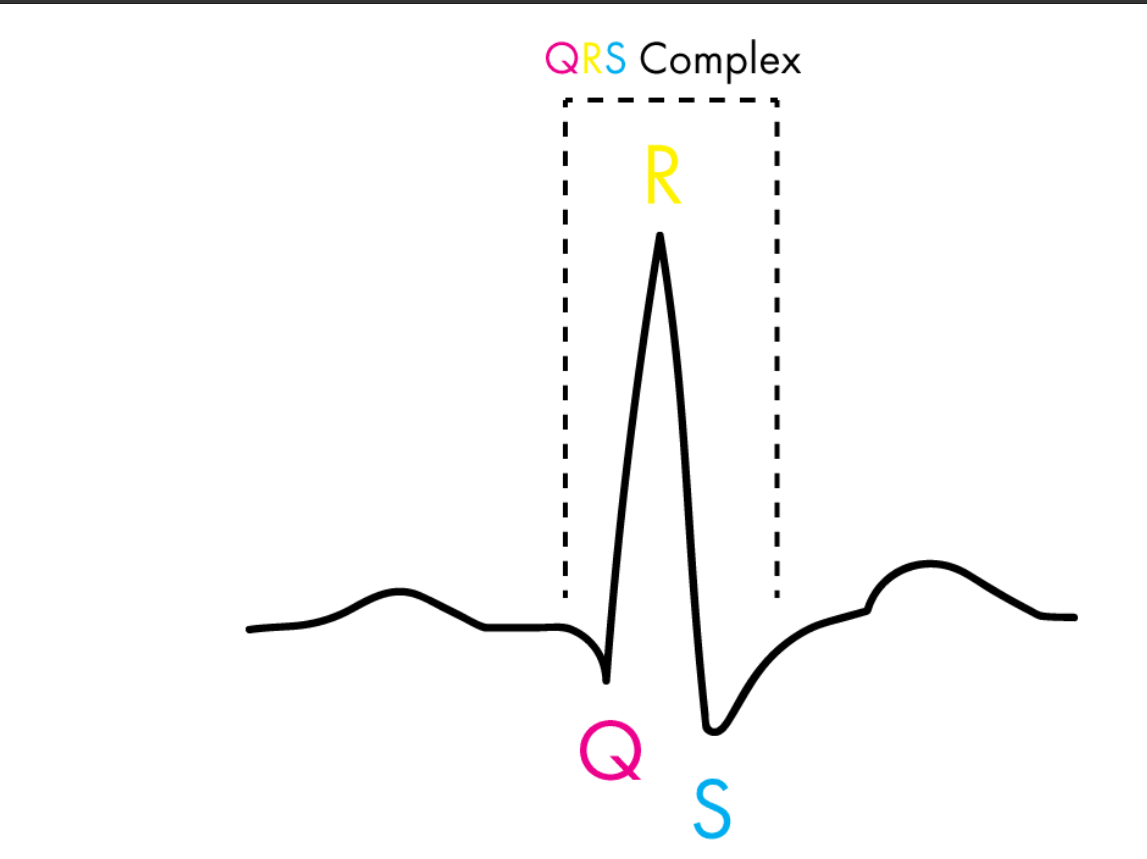

This is known as the **QRS complex**, with each letter corresponding to a  different part of the heart’s action. 

- The important thing to note is  that the “**R**” of the complex is the area from which the values for  analysis are taken. When we have several heartbeats next to each other,  then the distance (in milliseconds) between each “R” is defined as the  “**RR interva**l” (or sometimes the “**NN interval**” to emphasize that the  heartbeats are normal).

## Part b)

Physiological variation of the interval between consecutive heartbeats  is known as the heart rate variability (HRV). HRV analysis is  traditionally performed on electrocardiograms (ECG signals) and has  become a useful tool in the diagnosis of different clinical and  functional conditions. 

One of the first things to know when understanding heart rate is that  the most informative metric relies not just on the heart rate, but how  much the heart rate *varies*. What’s often at first glance counter-intuitive about this metric is that a *higher* heart rate variability (HRV) is associated with good health – the more  your heart jumps around (to an extent, of course), the readier you are  for action. On the other hand, a low HRV is associated with ill health.

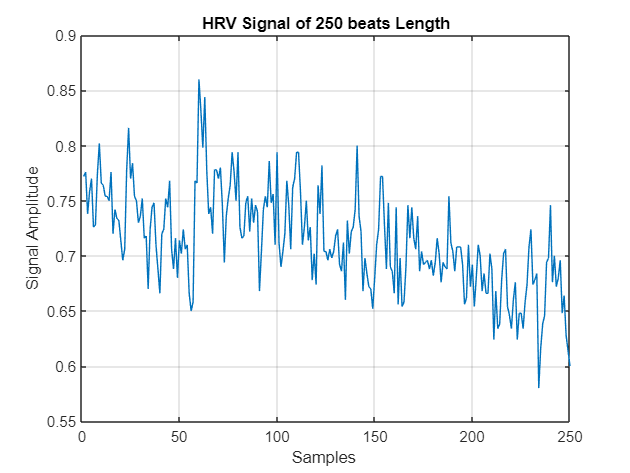

% Heart Rate Variability Analysis on Electrocardiograms
HRV_Signal_parent = load("HRV_signal.mat");
HRV_Signal = HRV_Signal_parent.HRV_signal;  

%% Plotting of HRV Signal
figure(2)
plot(HRV_Signal)
grid on
title("HRV Signal of 250 beats Length");
xlabel("Samples ")
ylabel("Signal Amplitude")

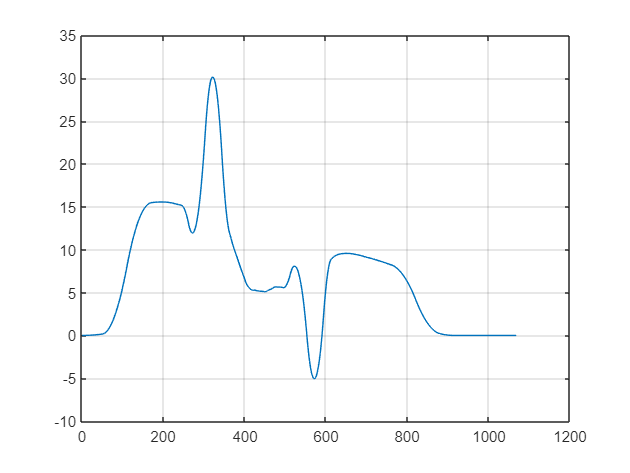

% Find the Time length of HRV SIgnal: --- >>> Using COrrelation with the
% original 0.8 second ECG Signal:


 Correlation_ECG = conv(ECG_Sig , HRV_Signal);
 figure(3)
 plot(Correlation_ECG)
 grid on


[peaks_ECG , idx ]=  findpeaks(Correlation_ECG);
% HRV is the RR intervals of ECG Respectedly of 250 ECG Beats!
ECG_Sig_Recovered = [];
for i=1:length(HRV_Signal)
    Next_ECG = circshift(ECG_Sig,round(HRV_Signal(i)/ts  ));
    ECG_Sig_Recovered  = [ECG_Sig_Recovered , Next_ECG ] ;
end

Signal_recovered_Time =  linspace(0, length(ECG_Sig_Recovered)*ts-ts ,length(ECG_Sig_Recovered));


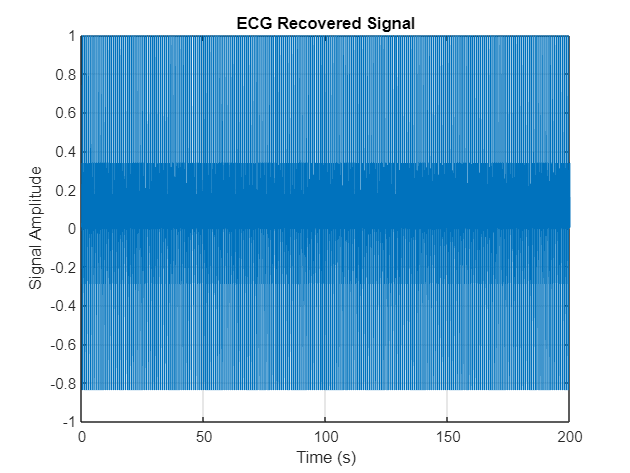


 figure(4)
 plot(Signal_recovered_Time , ECG_Sig_Recovered)
 grid on
 xlabel("Time (s)");
 ylabel("Signal Amplitude");
 title("ECG Recovered Signal")

## Part C)

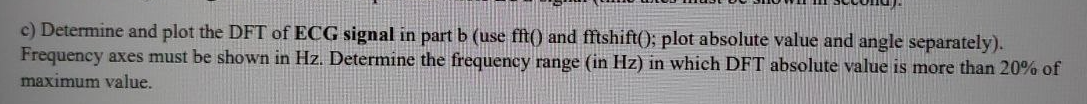

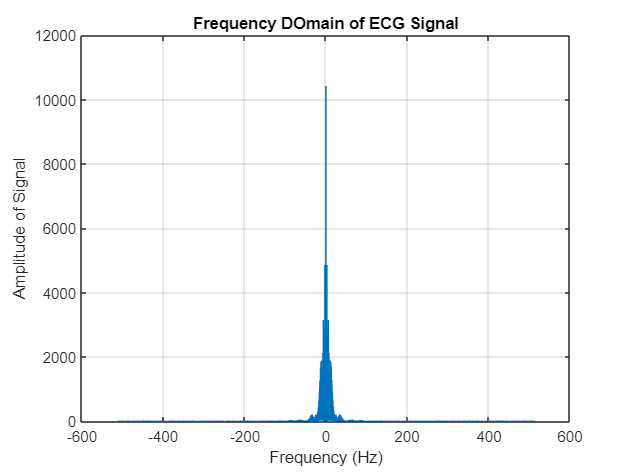

T_recording = Signal_recovered_Time(end);
delta_f = 1/T_recording;
ECG_DFT  = fftshift(fft(ECG_Sig_Recovered));
freq_rec = -fs/2:delta_f:fs/2;


figure(5)
plot(freq_rec , abs(ECG_DFT))
grid on
xlabel("Frequency (Hz)")
ylabel("Amplitude of Signal")
title("Frequency DOmain of ECG Signal")

% Determination of the frequency range in which the Signal in Frequency
% domain is higher than 20% of the maximum amplitude:

Frequency_range1 = freq_rec(abs(ECG_DFT)>20*max(ECG_DFT)/100);
BW = Frequency_range1(end) - Frequency_range1(1); % Bandwidth




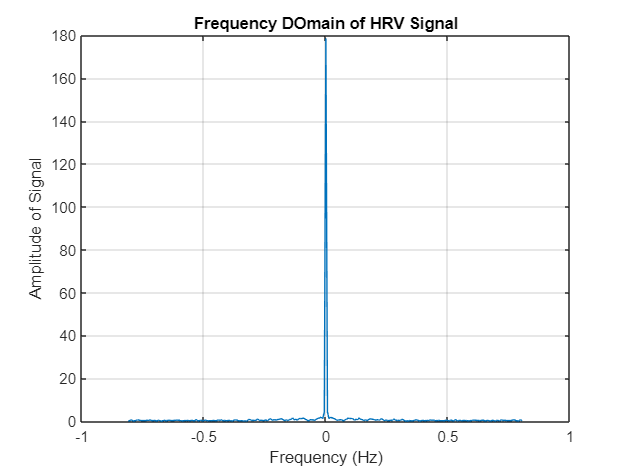


fs2 = 1.62; % Sampling Freq for HRV signal
ts2 = 1/fs2;
Trecord2 = length(HRV_Signal_DFT)*ts2;
deltaf_2 = 1/Trecord2;
freq_HRV = -fs2/2:deltaf_2:fs2/2-deltaf_2;

HRV_Signal_DFT  = fftshift(fft(HRV_Signal));



figure(6)
plot(freq_HRV, abs(HRV_Signal_DFT))
grid on
xlabel("Frequency (Hz)")
ylabel("Amplitude of Signal")
title("Frequency DOmain of HRV Signal")


Frequency_range2 = freq_HRV(abs(HRV_Signal_DFT)>20*max(abs(HRV_Signal_DFT))/100);
BW2 = Frequency_range2(end) - Frequency_range2(1); % Bandwidth